# **Eksamen M4STI1 2019E**

### Løsningsforslag af Allan Leck Jensen

## Opgave 1 - Fejl i printede emner

Oplysninger i opgaven:

clear; close all; clc; format compact;
n = 1000        % Antal testede emner

n = 1000

f = 45          % Antal fejl (revner)

f = 45

#### **a. Hvad er sandsynligheden for at emnet er fejlfrit (dvs. ingen mikroskopiske revner)?**

Et tilfældigte emne kan indeholde 0 eller flere fejl, der er ingen øvre grænse. Vi bruger poissonfordelingen. Lambda er det forventede antal fejl per emne. Det kan vi estimere som antal observerede fejl delt med antal emner:

lambda = f/n

lambda = 0.0450

Nu kan vi beregne sandsynligheden for 0 fejl på emnet med poissonfordelingens tæthedsfunktion poisspdf:

P_0_fejl = poisspdf(0, lambda)

P_0_fejl = 0.9560

P_0_fejl =** 0.9560**. 

#### **b. Hvad er sandsynligheden for at emnet har præcis 1 fejl?**

Vi bruger poisspdf igen: 

P_1_fejl = poisspdf(1, lambda)

P_1_fejl = 0.0430

P_1_fejl = **0.0430**.

#### **c. Hvad er sandsynligheden for at de alle er fejlfri?**

Nu har vi et batch på 120 emner, så der kan ikke være mere end 120 fejlfri emner. Derfor skal vi bruge binomialfordelingens tæthedsfunktion, binopdf. Man kan forestille sig, at vi gentager det samme forsøg 120 gange, nemlig at printe et emne 120 gange. Hver gang er der den samme sandsynlighedfor at emnet er fejlfrit, hvilket er succes, S. Vi kalder den sandsynlighed for p, så P(S) = p. Sandsynligheden for fejl er det komplementære til succes, så P(F) = 1-p. Sandsynligheden p er altså sandsynligheden for 0 fejl i et givet emne. Den sandsynlighed har vi fundet i a. til at være P_0_fejl.

N = 120

N = 120

p = P_0_fejl

p = 0.9560

P_alle_fejlfri = binopdf(N, N, p)

P_alle_fejlfri = 0.0045

P_alle_fejlfri = **0.0045**.

#### **d. Hvad er sandsynligheden for at 110 eller flere emner er fejlfri?**

Sandsynligheden for at 110 eller flere er fejlfri er det samme som 1 minus sandsynligheden for at 109 eller færre er fejlfri. Det kan vi beregne med binomialfordelingens kumulerede fordelingsfunktion binocdf:

P_mindst_110_fejlfri = 1 - binocdf(109, N, p)

P_mindst_110_fejlfri = 0.9829

P_mindst_110_fejlfri =** 0.9829**.

#### **e. Hvad er det forventede antal fejlfri emner?**

Det forventede antal fejlfri emner er sandsynligheden for et fejlfri emne gange antal emner. Dvs. det samme som middelværdien af binomialfordelingen:

fejlfri_middel = N*p

fejlfri_middel = 114.7197

fejlfri_middel = **114.7197**. 

## Opgave 2: Præcisionen af printeren

Jeg starter med at rydde op og indlæse data fra regnearket:

clc; clear; close all; format compact; 
D = xlsread('Data_M4STI1_2019E', 'A:B');
oensket = D(:,1);
opnaaet = D(:,2);
n = size(D,1)

n = 24

#### a. Beregn afvigelsen, delta, som forskellen på den ønskede og den opnåede bredde, og plot afvigelsen som funktion af den ønskede bredde

delta = oensket - opnaaet

delta =     0.2000
   -0.1000
   -0.3000
   -0.1000
    0.8000
    0.2000
    0.6000
   -0.5000
    1.0000
    0.1000


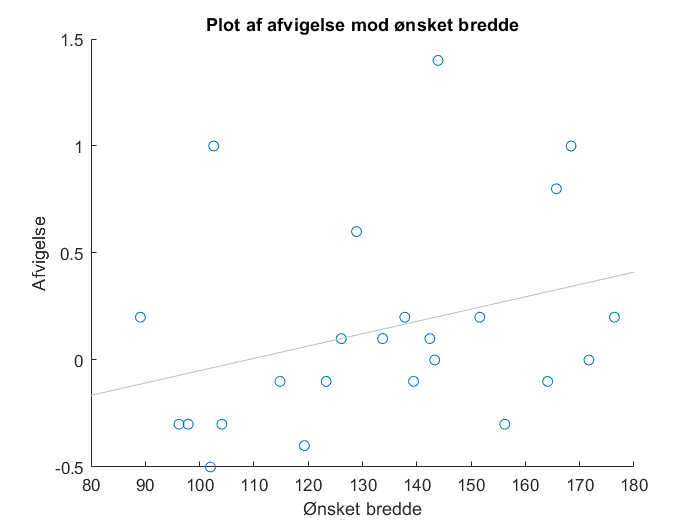

figure(1)
scatter(oensket, delta)
lsline
title('Plot af afvigelse mod ønsket bredde')
xlabel('Ønsket bredde')
ylabel('Afvigelse')

#### b. Giv en kvalificeret vurdering af, om man kan beskrive afvigelsen som en lineær funktion af den ønskede bredde

På figuren fra a. ses der en tendens til positiv korrelation, men med en del støj. Vi kan lave en lineær regression og teste om korrelationen er reel, dvs. om hældningskoefficienten er signifikant forskellig fra 0.

mdl = fitlm(oensket, delta)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue 
                   _________    _______    _______    _______
    (Intercept)      -0.6255    0.51174    -1.2223    0.23453
    x1             0.0057557    0.00377     1.5267    0.14108

Number of observations: 24, Error degrees of freedom: 22
Root Mean Squared Error: 0.475
R-squared: 0.0958,  Adjusted R-Squared: 0.0547
F-statistic vs. constant model: 2.33, p-value = 0.141

Der er ikke en lineær sammenhæng. Begge estimater af koefficienterne er ikke signifikant forskellige fra 0 (p-værdier hhv. 0.234 og 0.141). R-squared er kun 0.0958, så under 10 % af variationen beskrives af modellen. 

#### c. Giv din vurdering af, om afvigelsen er normalfordelt med middelværdi 0

delta_streg = mean(delta)

delta_streg = 0.1417

Jeg ville forvente, at middelværdien af afvigelsen ville være tættere på 0, hvis det var normalfordelt støj. Den er 0.14 mm. Det tyder på, at den opnåede bredde generelt er lidt under den ønskede.

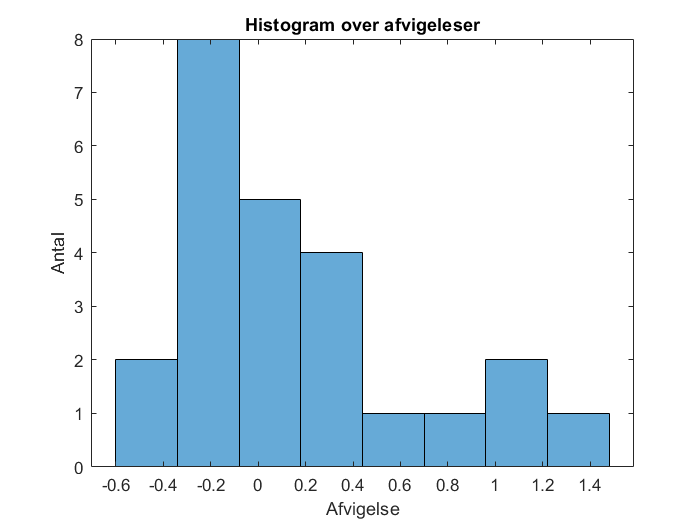

figure(2)
histogram(delta, 8)
title('Histogram over afvigeleser')
ylabel('Antal')
xlabel('Afvigelse')

Fordelingen af afvigelsen ser ud til at have et enkelt toppunkt, men ikke særlig symmetrisk. Fordelingen er højreskæv. 

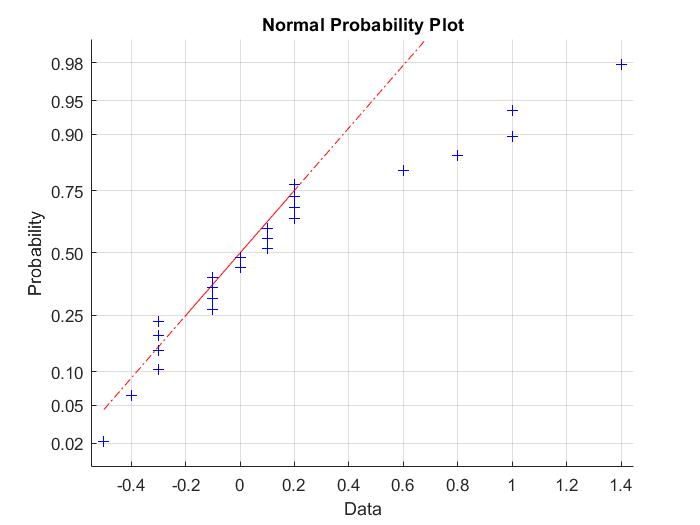

figure(3)
normplot(delta)

Data ligger ikke på en linje i normalfordelingsplottet, så afvigelserne tyder ikke på at være normalfordelte

#### d. Firmaet har en teori om, at den numeriske værdi af afvigelsen følger eksponentialfordelingen. Beregn et estimat for lambda under denne antagelse

Jeg finder den numeriske (absolutte) værdi af afvigelsen for hver måling og middelværdien af den. Estimatet for lambda er den reciprokke værdi af middelværdien:

absdelta = abs(delta);     
mu_hat = mean(absdelta)

mu_hat = 0.3500

lambda_hat = 1/mu_hat

lambda_hat = 2.8571

Estimatet for mu er 0.35.

Estimatet for lambda er **2.8571**.

#### e. Lav et histogram over den numeriske værdi af afvigelsen. Ser antagelsen om at den følger eksponentialfordelingen rimelig ud?

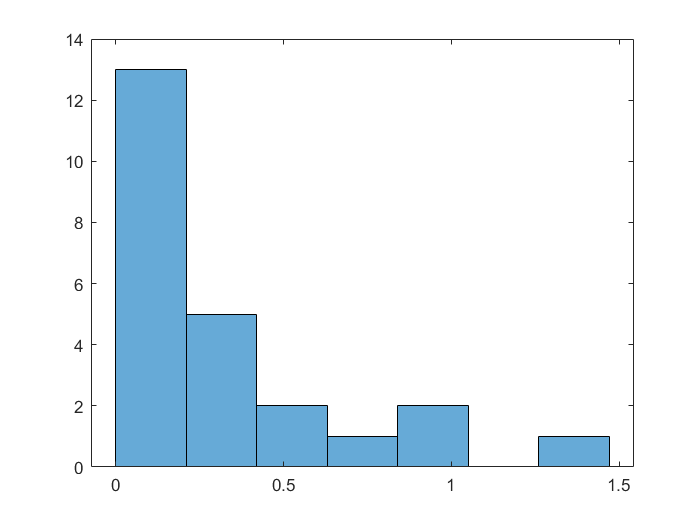

histogram(absdelta, 7)

Antagelsen ser rimelig ud. Den første kolonne er højst og så bliver de generelt lavere og lavere.

#### f. Opret k=5 kategorier, som de observerede og forventede værdier for den numeriske værdi af afvigelsen skal inddeles i til Goodness of Fit testen. Det anbefales at beregne grænserne mellem kategorierne, så der er lige mange forventede værdier i hver kategori

Jeg beregner grænserne for k=5 kategorier, så der forventes n/k i hver. Da n/k = 24/5 = 4.8 undgår vi på den måde, at skulle bruge tommelfingerreglen om at slå kategorier sammen, hvis det forventede antal er under 3. Her er det forventede antal 4.8 for alle kategorier. Jeg bruger den inverse kumulerede fordelingsfunktion for eksponentialfordelingen, expinv, til at beregne kategorigrænserne:

k = 5

k = 5

k0 = 0

k0 = 0

k1 = expinv(1/5, mu_hat)

k1 = 0.0781

k2 = expinv(2/5, mu_hat)

k2 = 0.1788

k3 = expinv(3/5, mu_hat)

k3 = 0.3207

k4 = expinv(4/5, mu_hat)

k4 = 0.5633

k5 = Inf    % Inf er uendelig

k5 = Inf

kateg = [k0, k1, k2, k3, k4, k5]

kateg =          0    0.0781    0.1788    0.3207    0.5633       Inf


Her er de 5 kategorier:

1: k0 til k1:     [0; 0.0781[

2: k1 til k2:     [0.0781; 0.1788[

3: k2 til k3:     [0.1788; 0.3207[

4: k3 til k4:     [0.3207; 0.5633[

5: k4 til k5:     [0.5633; Inf[

#### g. Vis antal observerede O og antal forventede E i hver kategori. For nogle kan det være enklere at bruge et andet værktøj end MATLAB til dette, f.eks. Excel

Man kan sortere absdelta med funktionen sort() og så fordele de 24 observationer i de 5 kategorier. F.eks. er der 2 observationer i første kategori, nemlig de 2 med værdien 0. I anden kategori er der 7 observationer, der alle har værdien 0.1. O.s.v. for de resterende kategorier. Vi får: O = [2, 7, 8, 2, 5]

Alternativt kan man bruge MATLAB funktionen histcounts:

O = histcounts(absdelta, kateg)

O =      2     7     8     2     5


E = ones(1, k)*n/k      % Vi har lavet kategorierne, så der forventes n/k = 4.8 i hver

E =     4.8000    4.8000    4.8000    4.8000    4.8000


Selv om det er overflødigt kan jeg kan vise, at det forventede antal, f.eks. i kategori 3 [0.1788; 0.3207[, er 4.8:

E_3 = n*(expcdf(0.3207, mu_hat) - expcdf(0.1788, mu_hat))

E_3 = 4.7995

Nu samles det hele til en tabel:

resultat = [ kateg(1:5)', kateg(2:6)', O', E' ];
table = array2table(resultat, 'Variablenames', {'Fra', 'Til', 'O', 'E'})

table = 5×4 table
      Fra        Til      O     E 
    _______    _______    _    ___
          0     0.0781    2    4.8
     0.0781    0.17879    7    4.8
    0.17879     0.3207    8    4.8
     0.3207     0.5633    2    4.8
     0.5633        Inf    5    4.8

#### h. Opstil hypoteser for testen

H0: De absolutte afvigelser følger eksponentialfordelingen

Ha: De absolutte afvigelser følger *ikke* eksponentialfordelingen

#### i. Oplys hvilken fordeling teststørrelsen følger og beregn den kritiske værdi

Teststørrelsen følger en Chi-i-anden fordeling med k - p -1 frihedsgrader, hvor k er antal kategorier (k = 5) og p er antal estimerede parametre (vi har estimeret lambda, så p = 1):

alfa = 0.05

alfa = 0.0500

p = 1

p = 1

df = k - p - 1      

df = 3

chi2_kritisk = chi2inv(1-alfa,df)   

chi2_kritisk = 7.8147

chi2_kritisk = **7.8147**.

#### j. Beregn teststørrelsen og konkluder på hypotesetesten

chi2_0 = 0;
for i=1:k
    chi2_0 = chi2_0 + (O(i) - E(i))^2 / E(i);
end
chi2_0

chi2_0 = 6.4167


p_vaerdi = 1 - chi2cdf(chi2_0, df)

p_vaerdi = 0.0930

**Konklusion**: Da teststørrelsen chi2_0 = **6.4167** ikke overstiger den kritiske værdi chi2_kritisk = **7.8147** kan vi ikke forkaste nulhypotesen H0. Dermed kan vi tro på, at den absolutte afvigelse følger eksponentialfordelingen. Dog er p-værdien **0.0930** ikke særligt stor. Det er ikke langt fra, at vi måtte forkaste nulhypotesen. 

## Opgave 3 - Brudstyrke

Jeg rydder op, indlæser data og bestemmer grundlæggende variable:

clc; clear; close all; format compact; 
D = xlsread('Data_M4STI1_2019E', 'D:G');
x = D(:,1:3)

x =      1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     2
     1     1     2
     1     1     2
     1     1     2


y = D(:,4)

y =    556
   502
   527
   511
   613
   596
   605
   612
   601
   611


Hastighed = x(:,1);
Tykkelse = x(:,2);
Temperatur = x(:,3);
n = 6                   % Der er 6 gentagelser

n = 6

#### a. Lav et parallelt boksplots for hver faktor, der viser forskelle i brudstyrke for faktorens niveauer. Beskriv diagrammerne

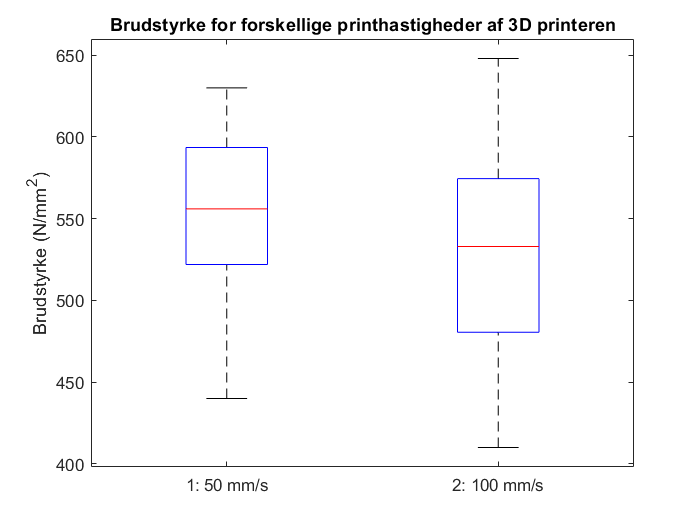

figure(1)
boxplot(y, Hastighed, 'labels', {'1: 50 mm/s'; '2: 100 mm/s'})
title('Brudstyrke for forskellige printhastigheder af 3D printeren')
ylabel('Brudstyrke (N/mm^2)')

De to boksplots for printhastighed ser nogenlunde ensartede ud. De har nogenlunde lige store kasser (interkvartil range) og ensartede koste. Måske er der en tendens til højere brudstyrke og mindre variation med den langsomme printhastighed.

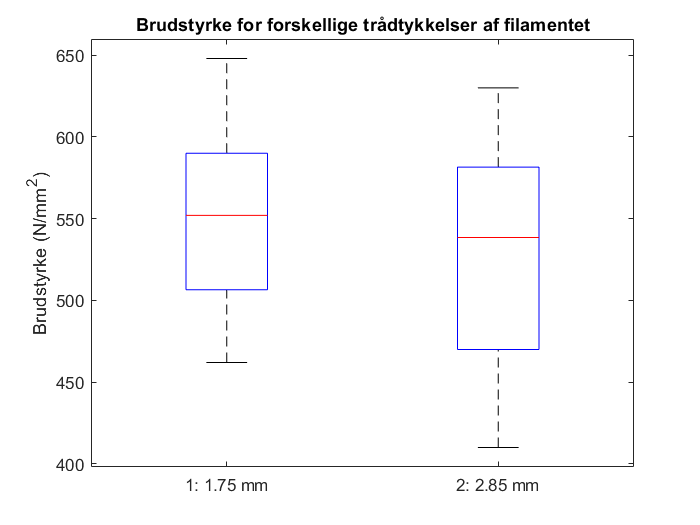

figure(2)
boxplot(y, Tykkelse, 'labels', {'1: 1.75 mm'; '2: 2.85 mm'})
title('Brudstyrke for forskellige trådtykkelser af filamentet')
ylabel('Brudstyrke (N/mm^2)')

De to boksplots for trådtykkelser ser også nogenlunde ensartede ud. Måske er der en tendens til højere brudstyrke og mindre variation med den tynde trådtykkelse.

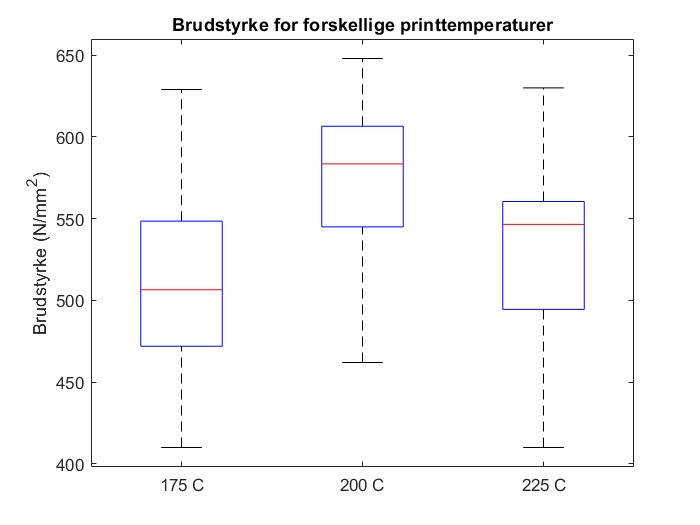

figure(3)
boxplot(y, Temperatur, 'labels', {'175 C'; '200 C'; '225 C'})
title('Brudstyrke for forskellige printtemperaturer')
ylabel('Brudstyrke (N/mm^2)')

De tre boksplots for printtemperataur ser også nogenlunde ensartede ud. Her er der en tendens til højere brudstyrke ved 200 grader. Medianen for 225 grader ligger over medianen for 175 grader, men de to har ensartede koste og interkvartile ranges.

#### b. Lav en variansanalyse (ANOVA) på signifikansniveau 5 %, der belyser om der er signifikant effekt af hver af de tre faktorer på brudstyrken. Er der signifikante 2-faktor og 3-faktor interaktioner?

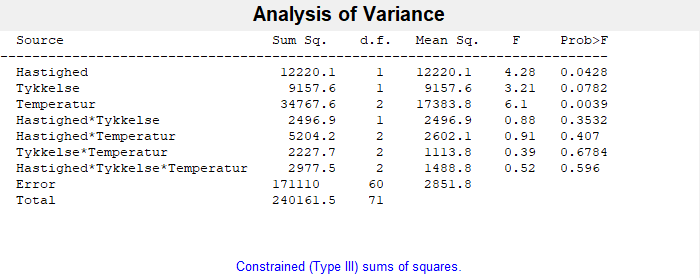

p =     0.0428
    0.0782
    0.0039
    0.3532
    0.4070
    0.6784
    0.5960


table = 10×7 cell array
    {'Source'                       }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'  }
    {'Hastighed'                    }    {[1.2220e+04]}    {[   1]}    {[        0]}    {[1.2220e+04]}    {[  4.2850]}    {[  0.0428]}
    {'Tykkelse'                     }    {[9.1576e+03]}    {[   1]}    {[        0]}    {[9.1576e+03]}    {[  3.2111]}    {[  0.0782]}
    {'Temperatur'                   }    {[3.4768e+04]}    {[   2]}    {[        0]}    {[1.7384e+04]}    {[  6.0957]}    {[  0.0039]}
    {'Hastighed*Tykkelse'           }    {[2.4969e+03]}    {[   1]}    {[        0]}    {[2.4969e+03]}    {[  0.8755]}    {[  0.3532]}
    {'Hastighed*Temperatur'         }    {[5.2042e+03]}    {[   2]}    {[        0]}    {[2.6021e+03]}    {[  0.9124]}    {[  0.4070]}
    {'Tykkelse*Temperatur'          }    {[2.2277e+03]}    {[   2]}    {[        0]}    {[1.1138e+03]}    {[  0.3906]}    {[  0.6784]}
    {'Hastighed*Tykkelse*Temper

stats = struct with fields:
         source: 'anovan'
          resid: [72×1 double]
         coeffs: [36×1 double]
            Rtr: [12×12 double]
       rowbasis: [12×36 double]
            dfe: 60
            mse: 2.8518e+03
    nullproject: [36×12 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {36×1 cell}
           vars: [36×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1
     1     1     1


[p,table,stats,terms] = anovan(y, x, 'model','full',...
    'varnames',{'Hastighed','Tykkelse','Temperatur'})

Der er signifikant forskel på hastighederne         (p = 0.0428 < 0.05)

Der er **ikke** signifikant forskel på tykkelserne      (p = 0.0782 > 0.05)

Der er signifikant forskel på temperaturerne       (p = 0.0039 < 0.05)

Der er hverken 2-faktor eller 3-faktor interaktioner, idet alle p-værdierne for disse tests er klart over signifikansniveauet på 5 %

#### c. Lav en parvis sammenligning af brudstyrken for de tre temperaturer med LSD metoden. For hvilke temperaturer er brudstyrkerne forskellige på 5 % signifikansniveau? Hvad er 95 % konfidensintervallet for forskellen på brudstyrkerne for de tre temperaturer?

Jeg skal bruge multcompare på den tredje faktor, temperatur, så 'Dimension' skal være [3]:

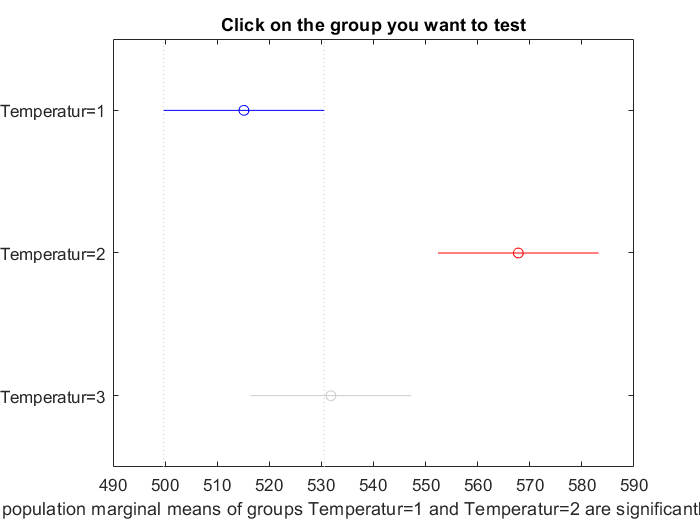

c =     1.0000    2.0000  -83.5032  -52.6667  -21.8301    0.0011
    1.0000    3.0000  -47.5449  -16.7083   14.1282    0.2828
    2.0000    3.0000    5.1218   35.9583   66.7949    0.0230


m =   515.1250   10.9008
  567.7917   10.9008
  531.8333   10.9008


[c,m] = multcompare(stats, 'Alpha',0.05, 'CType','lsd', 'Dimension', 3)

Ved at aflæse i grafikken ser vi, at temperatur 2 (200 C) giver signifikant højere brudstyrke end begge de andre temperaturer. Brudstyrken er ikke signifikant forskellig for temperatur 1 (175 C) og temperatur 3 (225 C). 

95% konfidensintervaller for forskelle mellem temperaturer er:

1 og 2:   (-83.5; -21.8)

1 og 3:   (-47.5; 14.13)

2 og 3:   (5.1; 66.8)

Vi ser at den sande forskel i brudstyrke mellem temperatur 1 og 3 kan være 0, da 0 er i konfidensintervallet (-47.5; 14.13). Den tilhørende p-værdi er 0.2828. 

De to andre konfidensintervaller indeholder ikke 0 og deres p-værdier er under 0.05. Det underbygger resultatet fra grafikken, at temperatur 2 er forskellig fra både 1 og 3, men temperatur 1 og 3 er ikke signifikant forskellige.

#### **d. Hvilken kombination af hastighed, trådtykkelse og temperatur giver den bedste (højeste) brudstyrke og hvilken giver den dårligste (laveste)? Er der signifikant forskel på de to kombinationer på 5 % signifikansniveau?**

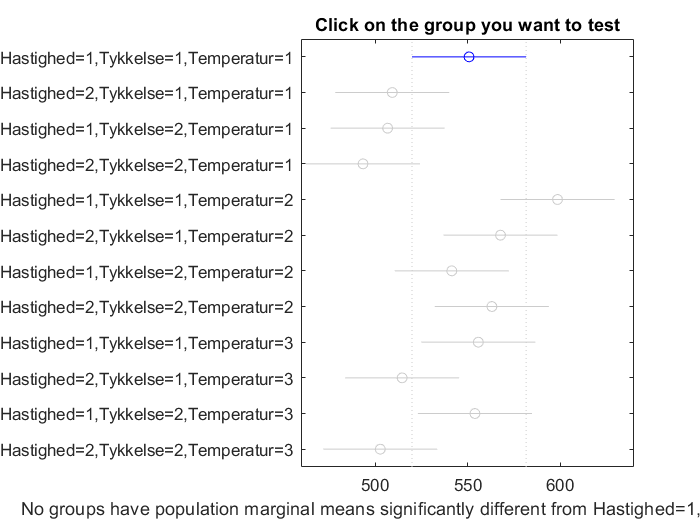

c =     1.0000    2.0000  -20.1731   41.5000  103.1731    0.1834
    1.0000    3.0000  -17.6731   44.0000  105.6731    0.1587
    1.0000    4.0000   -4.3398   57.3333  119.0065    0.0679
    1.0000    5.0000 -109.5065  -47.8333   13.8398    0.1261
    1.0000    6.0000  -78.6731  -17.0000   44.6731    0.5834
    1.0000    7.0000  -52.3398    9.3333   71.0065    0.7632
    1.0000    8.0000  -74.0065  -12.3333   49.3398    0.6906
    1.0000    9.0000  -66.6731   -5.0000   56.6731    0.8717
    1.0000   10.0000  -25.5065   36.1667   97.8398    0.2454
    1.0000   11.0000  -64.8398   -3.1667   58.5065    0.9185


m =   550.8333   21.8015
  509.3333   21.8015
  506.8333   21.8015
  493.5000   21.8015
  598.6667   21.8015
  567.8333   21.8015
  541.5000   21.8015
  563.1667   21.8015
  555.8333   21.8015
  514.6667   21.8015


[c,m] = multcompare(stats,'Alpha',0.05, 'CType','lsd', 'Dimension', [1,2,3])

Grafikken fra multcompare viser, at den bedste kombination er hastighed 1, tykkelse 1 og temperatur 2 (den 5. kombination). I matricen m, som er output fra multcompare kan jeg aflæse, at den kombination har en forventet (gennemsnitlig) brudstyrke på 598.7 N/mm2, hvilket er den højeste værdi.

Den dårligste kombination er hastighed 2, tykkelse 2 og temperatur 1 (kombination 4) med en gennemsnitlig brudstyrke på 493.5 N/mm2. 

Grafikken viser også, at de to kombinationer er signifikant forskellige. P-værdien i sammenligningen af disse to kombinationer (4 og 5) aflæses i c-matricen til 0.0012.

#### e. Hvilke antagelser for residualerne er der gjort i denne statistiske model? Undersøg med grafiske eller statistiske metoder, om antagelserne holder.

Vi har antaget, at residualerne er normalfordelte med middelværdi 0 og med samme varians for hver faktor (varianshomogenitet). Residualer findes i stats objektet, lavet af anovan

resid = stats.resid

resid =     5.1667
  -48.8333
  -23.8333
  -39.8333
   62.1667
   45.1667
    6.3333
   13.3333
    2.3333
   12.3333


Vi kan teste om residualerne er normalfordelte med et normalfordelingsplot:

figure(4)
normplot(resid)

Residualerne ligger nogenlunde på en ret linje (dog ikke den røde linje i grafikken), så de lader til at være normalfordelte, som antaget

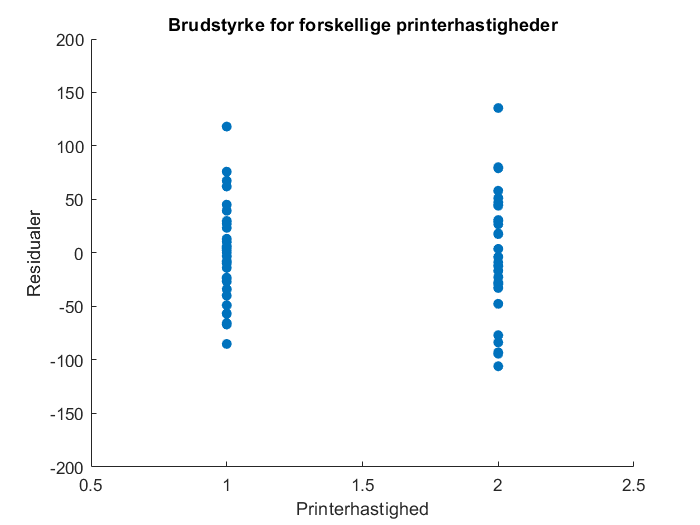

figure(5)
scatter(Hastighed, resid, 'filled')
xlabel('Printerhastighed')
ylabel('Residualer')
title('Brudstyrke for forskellige printerhastigheder')
axis([0.5 2.5 -200 200])

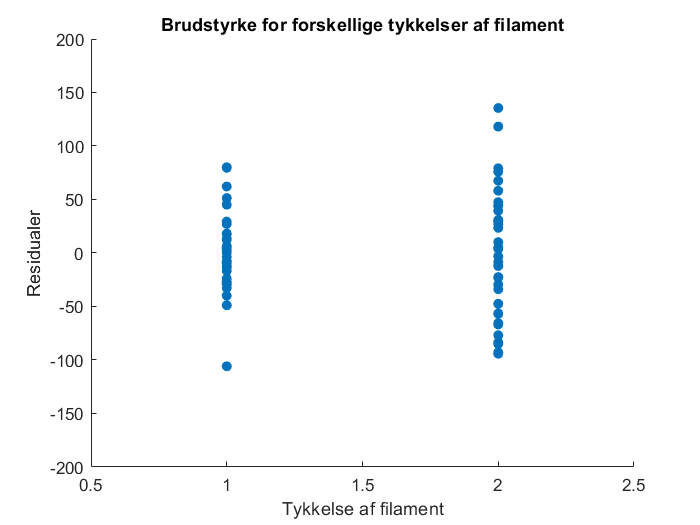


figure(6)
scatter(Tykkelse, resid, 'filled')
xlabel('Tykkelse af filament')
ylabel('Residualer')
title('Brudstyrke for forskellige tykkelser af filament')
axis([0.5 2.5 -200 200])

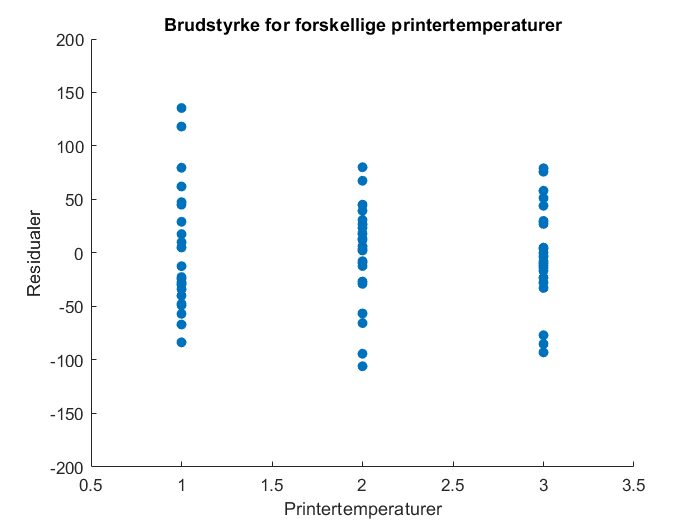


figure(7)
scatter(Temperatur, resid, 'filled')
xlabel('Printertemperaturer')
ylabel('Residualer')
title('Brudstyrke for forskellige printertemperaturer')
axis([0.5 3.5 -200 200])

Alle tre residualplots er nogenlunde ensartede, så antagelsen om varianshomogenitet lader til at være opfyldt.

Alternativt kan vi lave en Bartlett's test for hver faktor 

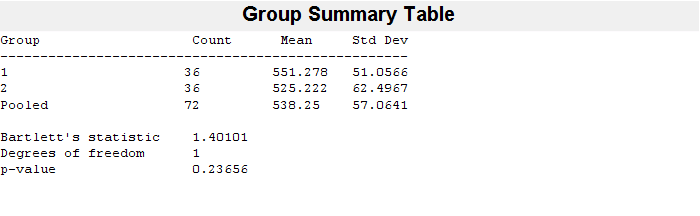

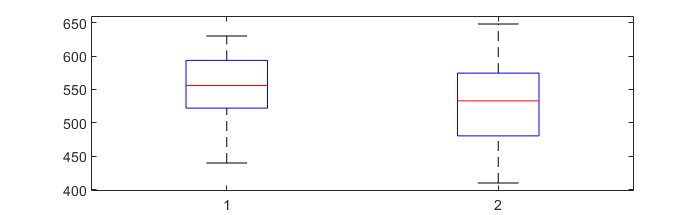

ans = 0.2366

vartestn(y, Hastighed)

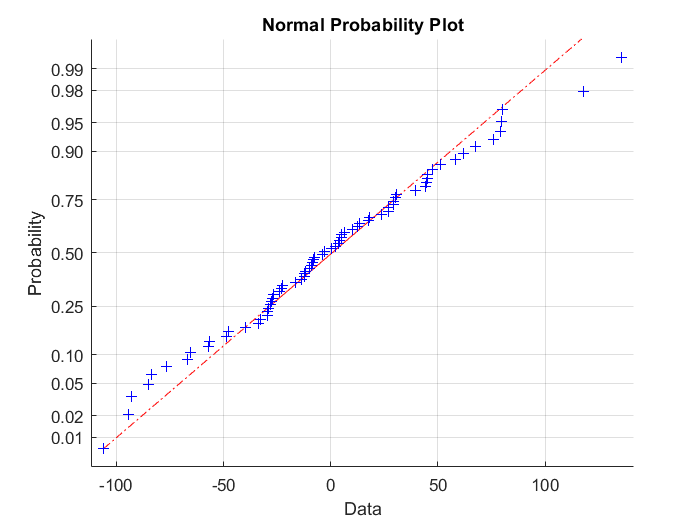

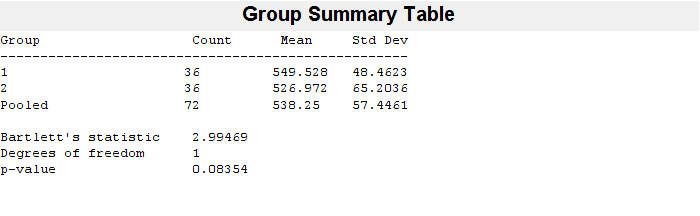

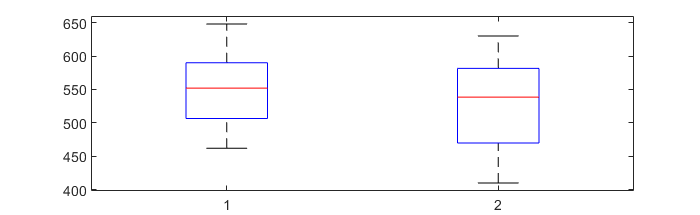

ans = 0.0835

vartestn(y, Tykkelse)

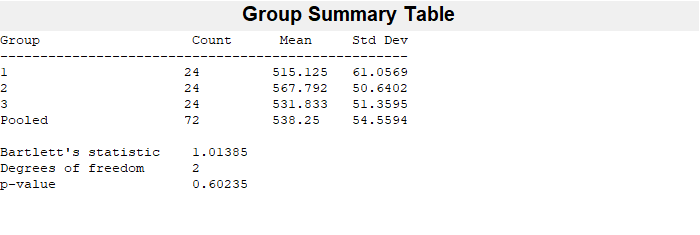

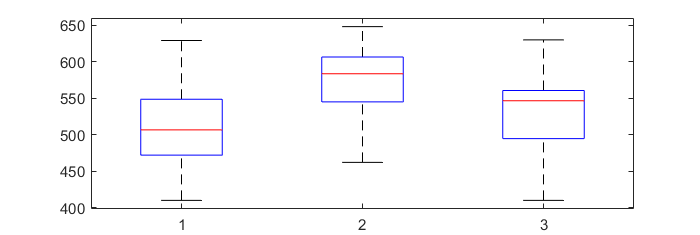

ans = 0.6023

vartestn(y, Temperatur)

For hver test er p-værdien over 5%, så vi kan ikke forkaste nulhypotesen, som siger, at variansen er ens. Vi kan således gå ud fra, at variansen er ens for alle faktorniveauer, som vi har antaget. De visuelle forskelle fra plots er ikke store nok til at være signifikante. 